pd = 0.9;            % Probability of detection
pfa = 1e-6;          % Probability of false alarm
max_range = 10e3;    % Maximum unambiguous range
range_res = 20;      % Required range resolution
tgt_rcs = 1;         % Required target radar cross section

import radarplot.*


%% Monostatic Radar System Design

prop_speed = 3e8;   % Propagation speed
pulse_bw = prop_speed/(2*range_res);    % Pulse bandwidth
pulse_width = 1/pulse_bw;               % Pulse width
prf = prop_speed/(2*max_range);         % Pulse repetition frequency
fs = 2*pulse_bw; 



fc = 10e9;
ang = [0;0];
% resp = array(fc,ang);
% pattern(array,fc,[-180:180],0,'PropagationSpeed',prop_speed, ...
%     'CoordinateSystem','polar','Type','powerdb','Normalize',true);
% 
% pattern(array,fc,0, [-90:90],'PropagationSpeed',prop_speed, ...
%     'CoordinateSystem','polar','Type','powerdb','Normalize',true);

% % Sampling rate
waveform = phased.RectangularWaveform(...
    'PulseWidth',pulse_width,...
    'PRF',prf,...
    'OutputFormat', "Pulses",...
    "NumPulses", 1,...
    'SampleRate',fs,...
    "PRFOutputPort", true);

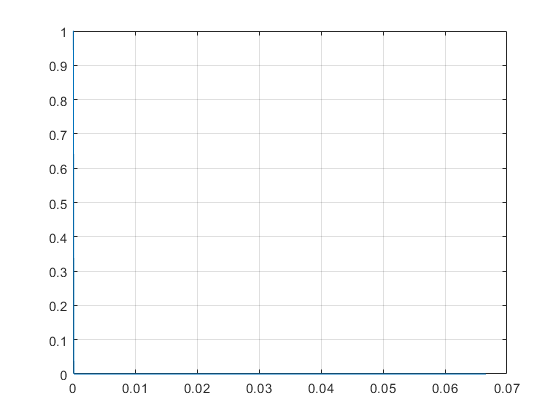

FrqWav= step(waveform);
FrqSamp= size(FrqWav, 1);
t1 = [0:(FrqSamp-1)]/fs;
plot(t1*1000, real(FrqWav));
grid

%Rx Noise Characteristics

noise_bw = pulse_bw;

receiver = phased.ReceiverPreamp(...
    'Gain',20,...
    'NoiseFigure',3,...
    'SampleRate',fs,...
    'EnableInputPort',true);



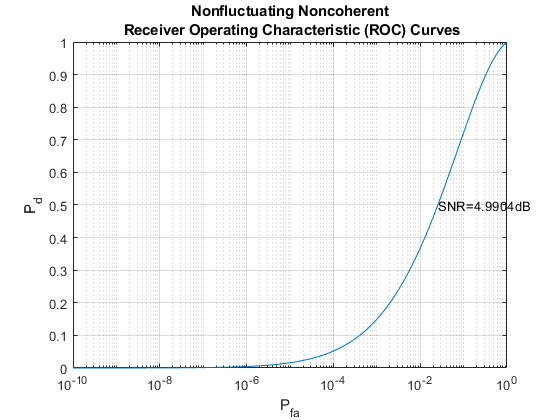


%Tx Design
SNR= snr_min;
snr_db = [-inf, 0, 3, 10, 13];
rocsnr(SNR,'SignalType','NonfluctuatingNoncoherent');


%In the Graph, we see that the required SNR for Pfa= 1e-6 and pd= 0.9 must exceed 13db,
% which is very unrealistic

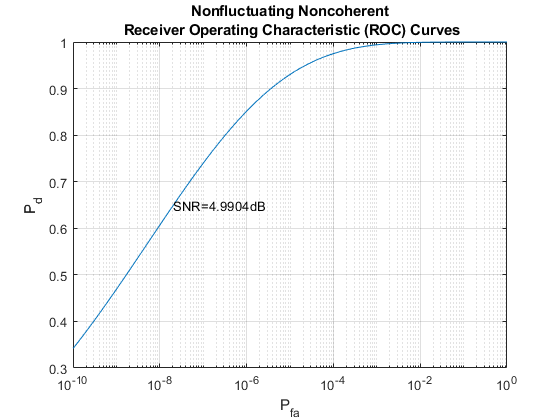


%Hence, we use Pulse Integration to reduce the SNR

% Using Coherent Integration, for better efficiency

num_pulse_int = 10;
rocsnr(SNR,'SignalType','NonfluctuatingNoncoherent',...
    'NumPulses',num_pulse_int);


snr_min = albersheim(pd, pfa, num_pulse_int)

snr_min = 4.9904

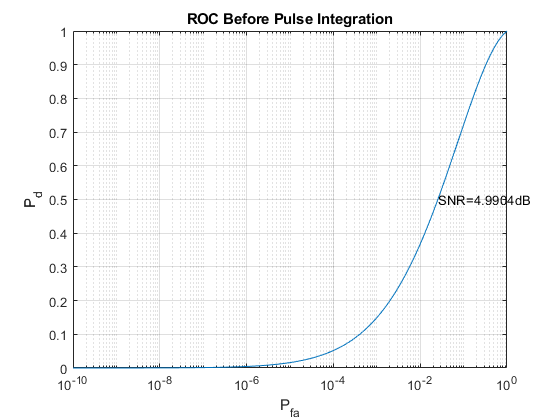

rocsnr(snr_min,'SignalType','NonfluctuatingNoncoherent');
title("ROC Before Pulse Integration")

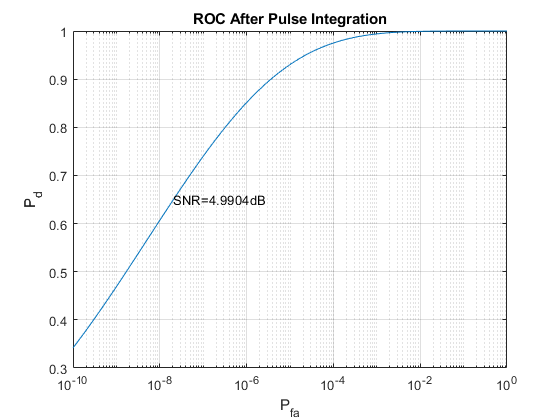

rocsnr(snr_min,'SignalType','NonfluctuatingNoncoherent','NumPulses',num_pulse_int);
title("ROC After Pulse Integration")

% Albershiem Equation Snr= A+ 0.12AB + 1.7B
% A= ln(0.62/Pfa) and B= ln(Pd/(1-Pd))



tx_gain = 20;

lambda = prop_speed/fc;

peak_power = radareqpow(lambda,max_range,snr_min,pulse_width,...
    'RCS',tgt_rcs,'Gain',tx_gain)

peak_power = 2.0891e+05


transmitter = phased.Transmitter(...
    'Gain',tx_gain,...
    'PeakPower',peak_power,...
    'InUseOutputPort',true);



% Radiator and Collector

% In a monostatic radar system, the radiator and the collector share the
% same antenna, so we will first define the antenna. To simplify the
% design, we choose an isotropic antenna.

% We assume that the antenna is stationary.

antenna = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e9 15e9]);

sensormotion = phased.Platform(...
    'InitialPosition',[0; 0; 0],...
    'Velocity',[0; 0; 0]);

radiator = phased.Radiator(...
    'Sensor',antenna,...
    'OperatingFrequency',fc);

collector = phased.Collector(...
    'Sensor',antenna,...
    'OperatingFrequency',fc);




%Simulation

%Test Targets

tgtpos = [[-1502;0;-100],[0;3100;0],[459;100;10], [559;-160;-1150], [59;-1000;100]];
tgtvel = [[0;0;0],  [0;0;0],    [0;0;0],        [0;0;0],        [0;0;0]];
tgtmotion = phased.Platform('InitialPosition',tgtpos,'Velocity',tgtvel);

tgtrcs = [1.6 2.2 10.05 5.5 0.99];
target = phased.RadarTarget('MeanRCS',tgtrcs,'OperatingFrequency',fc);

%Env Simulation

channel = phased.FreeSpace(...
    'SampleRate',fs,...
    'TwoWayPropagation',true,...
    'OperatingFrequency',fc);


fast_time_grid = unigrid(0,1/fs,1/prf,'[)');    % Time within the each pulse
slow_time_grid = (0:num_pulse_int-1)/prf;       %Time between tow successive pulses



receiver.SeedSource = 'Property';
receiver.Seed = 2009;


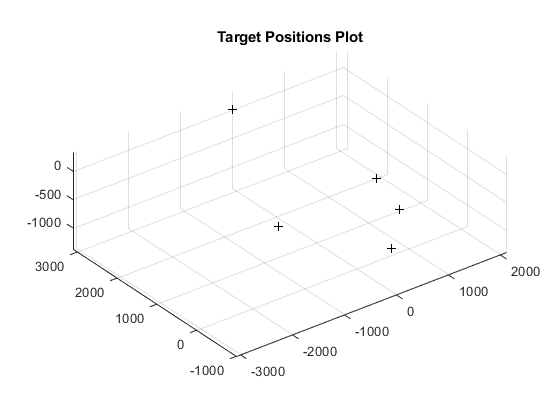

%% Range Plots


tgtcol= tgtpos';

txpos= tgtcol(:,1);
tyos= tgtcol(:, 2);
tzpos= tgtcol(:, 3);


Pl= alphaShape(txpos, tyos, tzpos);
plot(Pl, "FaceColor","none", "LineStyle","none", "Marker","+", "MarkerFaceColor","auto");
title("Target Positions Plot")

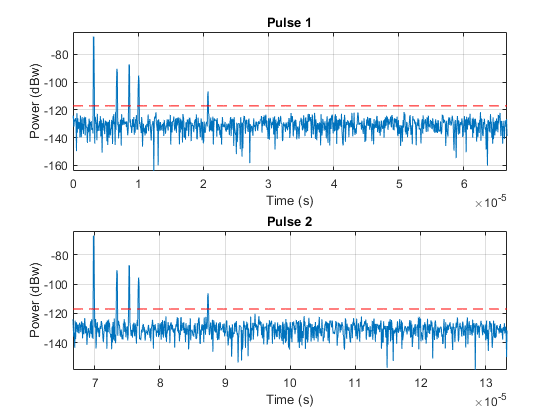


% Pre-allocating array for improved processing speeds
rxpulses = zeros(numel(fast_time_grid),num_pulse_int);

for m = 1:num_pulse_int
    
    % Update sensor and target positions
    [sensorpos,sensorvel] = sensormotion(1/prf);
    [tgtpos,tgtvel] = tgtmotion(1/prf);

    % Calculate the target angles as seen by the sensor
    [tgtrng,~] = rangeangle(tgtpos,sensorpos);
    
    % Simulate propagation of pulse in direction of targets
    pulse = waveform();
    [txsig,txstatus] = transmitter(pulse);
    txsig = radiator(txsig,tgtang);
    txsig = channel(txsig,sensorpos,tgtpos,sensorvel,tgtvel);
    
    % Reflect pulse off of targets
    tgtsig = target(txsig);
    
    % Receive target returns at sensor
    rxsig = collector(tgtsig,tgtang);
    rxpulses(:,m) = receiver(rxsig,~(txstatus>0));
    
     % Perform pulse integration every 'num_pulse_int' pulses
  
    
end


%% Range Detection

% The detector compares the signal power to a given threshold.

npower = noisepow(noise_bw,receiver.NoiseFigure,...
    receiver.ReferenceTemperature);
threshold = npower * db2pow(npwgnthresh(pfa,num_pulse_int,'noncoherent'));

%%
% Plotting the first two received pulses with the threshold
num_pulse_plot = 2;
helperRadarPulsePlot(rxpulses,threshold,...
    fast_time_grid,slow_time_grid,num_pulse_plot);




% The matched filter offers a processing gain which improves the detection threshold. 


matchingcoeff = getMatchedFilter(waveform);
matchedfilter = phased.MatchedFilter(...
    'Coefficients',matchingcoeff,...
    'GainOutputPort',true);
[rxpulses, mfgain] = matchedfilter(rxpulses);

%%
% The matched filter introduces an intrinsic filter delay so that the locations of the peak are identified.
 


matchingdelay = size(matchingcoeff,1)-1;
rxpulses = buffer(rxpulses(matchingdelay+1:end),size(rxpulses,1));

%%
% The threshold is then increased by the matched filter processing gain.
threshold = threshold * db2pow(mfgain);


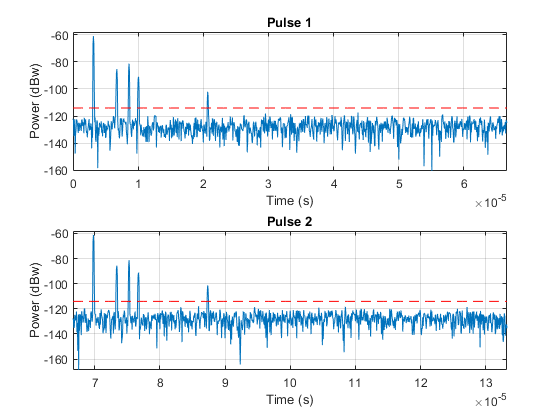


helperRadarPulsePlot(rxpulses,threshold,...
    fast_time_grid,slow_time_grid,num_pulse_plot);


%%
% After the matched filter stage, the SNR is improved.  However, because
% the received signal power is dependent on the range, the return of a
% close target is still much stronger than the return of a target farther
% away. Therefore, as the above figure shows, the noise from a close range
% bin also has a significant chance of surpassing the threshold and
% shadowing a target farther away.  To ensure the threshold is fair to all
% the targets within the detectable range, we can use a time varying gain
% to compensate for the range dependent loss in the received echo.
%
% To compensate for the range dependent loss, we first calculate the range
% gates corresponding to each signal sample and then calculate the free
% space path loss corresponding to each range gate. Once that information
% is obtained, we apply a time varying gain to the received pulse so that
% the returns are as if from the same reference range (the maximum
% detectable range).

range_gates = prop_speed*fast_time_grid/2; 

tvg = phased.TimeVaryingGain(...s
    'RangeLoss',2*fspl(range_gates,lambda),...
    'ReferenceLoss',2*fspl(max_range,lambda));

rxpulses = tvg(rxpulses);

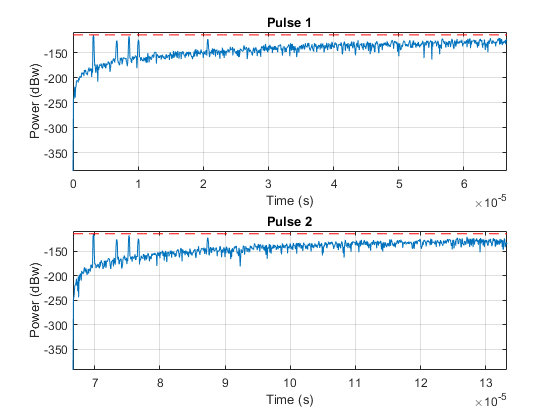


%%
%  plotting the same pulses after the range normalization 
helperRadarPulsePlot(rxpulses,threshold,...
    fast_time_grid,slow_time_grid,num_pulse_plot);

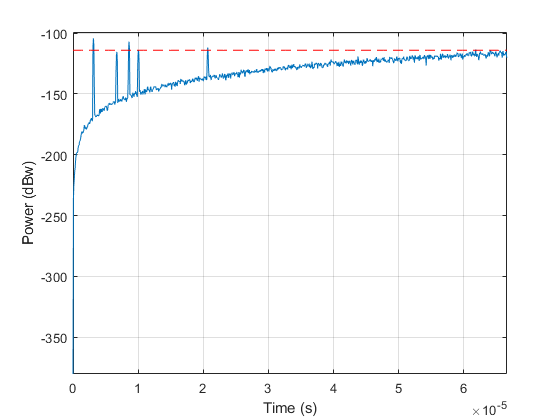



% The threshold is above the maximum power level
% contained in each pulse.  Therefore, nothing can be detected at this
% stage yet. 


% We can further improve the SNR by noncoherently integrating the received pulses.

rxpulses = pulsint(rxpulses,'noncoherent');

helperRadarPulsePlot(rxpulses,threshold,...
    fast_time_grid,slow_time_grid,1);



% Range Detection

[~,range_detect] = findpeaks(rxpulses,'MinPeakHeight',sqrt(threshold));

%% 
% The true ranges and the detected ranges of the targets are

true_range = round(tgtrng)

true_range =         1505        3100         470        1289        1007


range_estimates = (range_gates(range_detect))

range_estimates = 	1.0e+03 *

    0.4700    1.2900    1.5100    3.1000    9.2700



tgtazi= tgtang(1, :);
tgtele= tgtang(2, :);


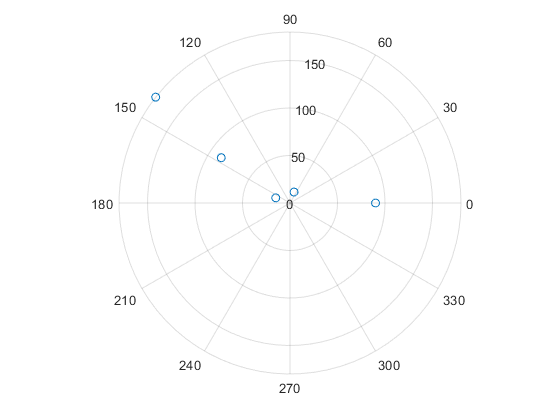


polarplot(tgtele, tgtazi,'o');



% radarplot(range_estimates, tgtazi);
% title("PPI Display (Azimutal Angle - Range)");
% 
% 
% % radarplot(range_estimates, tgtele);
% % title("Ele - Range");
% 
% 
% plot(tgtazi, tgtele, "Marker","+", "LineStyle","none");
% title("C Scope");
% xlabel("Azimutal Angle");
% ylabel("Elevation Angle");
% 
% plot(tgtazi,range_estimates, tgtele, range_estimates, "Marker","x", "LineStyle","none");
% title("B Scope/ E Scope");
% xlabel("Azimutal Angle/ Elevation Angle");
% ylabel("Range");
% legend("B Scope", "E Scope", "AutoUpdate","on")

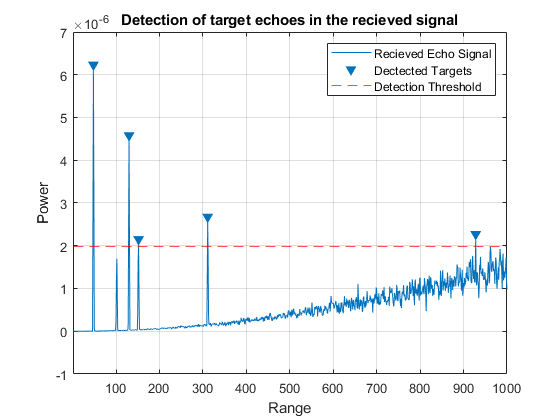

findpeaks(rxpulses, "MinPeakHeight",sqrt(threshold));
th= yline(sqrt(threshold), 'r--');
title("Detection of target echoes in the recieved signal");
xlabel("Range");
ylabel("Power");
legend("Recieved Echo Signal", "Dectected Targets", "Detection Threshold");

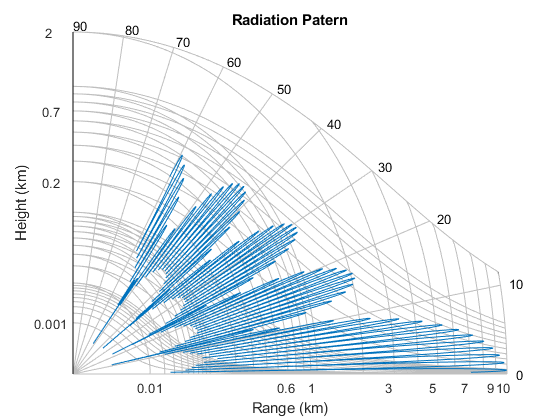

% Antenna Directivity Patterns
freq = fc;
ant_height = 1;
rng_fs = 5;
[vcp, vcpangles] = radarvcd(freq,rng_fs,ant_height);
blakechart(vcp, vcpangles);
title("Radiation Patern")

% Antenna Response Patterns
% 
% ele= sort(tgtele);
% azi= sort(tgtazi);
% 
% pattern(antenna,freq, azi, ele, 'CoordinateSystem','polar','Type','powerdb','Normalize',true,'PropagationSpeed',physconst('LightSpeed')  );
% 
% pattern(antenna,freq, 0, ele,'CoordinateSystem','polar','Type','powerdb',...
%     'Normalize',true);
% 
% pattern(antenna,freq, azi, 0,'CoordinateSystem','polar','Type','powerdb',...
%     'Normalize',true);

timeForDetection= range2time(range_estimates)

timeForDetection = 	1.0e+-4 *

    0.0314    0.0861    0.1007    0.2068    0.6184


% range= time2range(t)